%
% Choose a setup:
%
sSetup = "GeneralistsDiatoms";
sSetup

sSetup = "GeneralistsDiatoms"


p = eval( strcat('setup',sSetup) );
p = parametersWatercolumn(p);

latitude = 75;
longitude = -10;

p.tEnd = 5*365;
sim = simulateWatercolumn(p,latitude,longitude);

Preparing simulation
Starting simulation
Solving time:  0:00:09


p.tEnd = 365;
sim = simulateWatercolumn(p,latitude,longitude,sim);

Preparing simulation
Starting from previous simulation.
Starting simulation
Solving time:  0:00:01


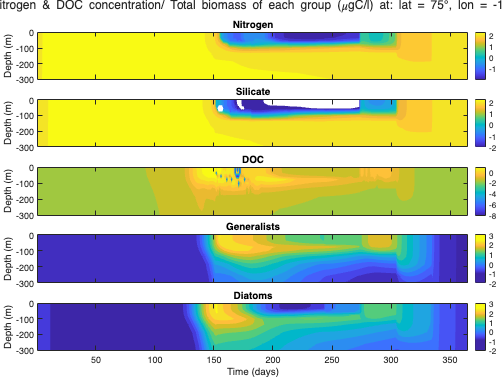


plotWatercolumnTime(sim, depthMax=300);

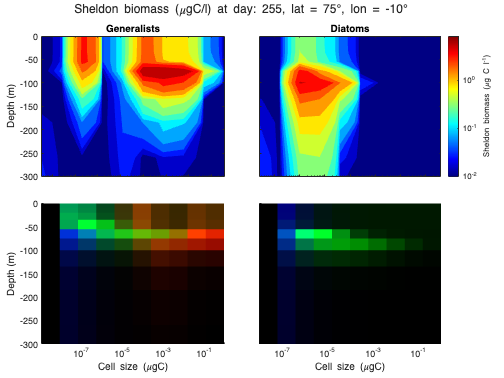

tDay = 255;
plotWatercolumn(sim, tDay, depthMax=300)

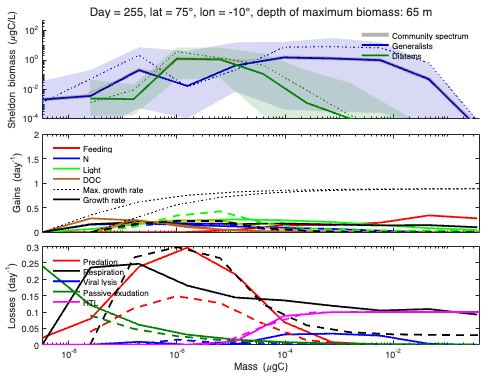

iDepth = 5;
         
plotSizespectrum(sim, tDay,iDepth);